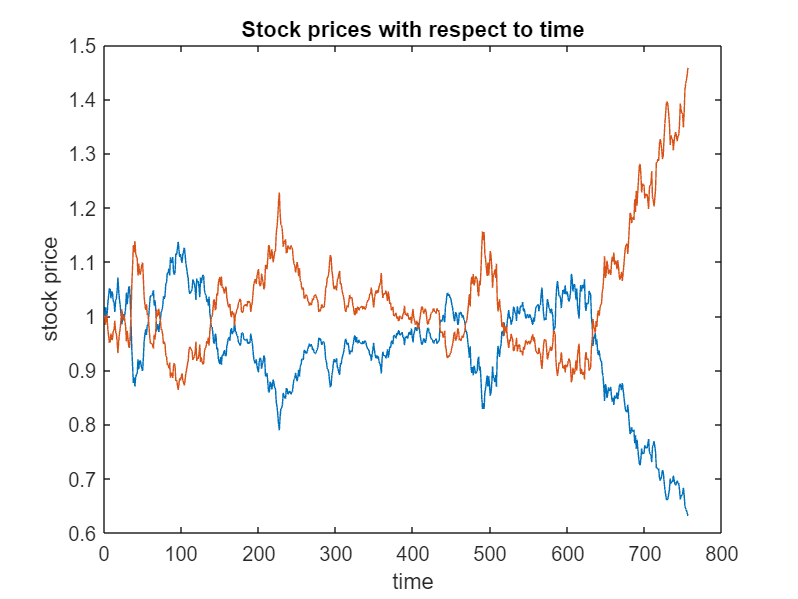

%---------------------------------------------------------------------|
% Extra problem for course Financial Mathematics                      |
% and Statistics                                                      |
%                                                                     |
%---------------------------------------------------------------------|
%                                                                     |
% Ellinoora Hetemaa                                           |
%                                                                     |
%---------------------------------------------------------------------|
%                                                                     |
% This code is implemented to price a European call up-and-in         |
% call option with parameters K = strike, H = barrier level,          |
% T = maturity time, S0 = the initial stok price, V0 = initial        |
% volatility                                                          |
%                                                                     |
% The code is written by using Monte Carlo simulation with            |
% anthithetic variates                                                |
%                                                                     |
%---------------------------------------------------------------------|

clear all;
clc;
close all;

% Initial parameters
S0 = 1;
V0 = 0.04;
K = 0.98;
H = 1.1;
T = 3;

model = 'Heston';

% Heston model parameters
r = 0.01;
kappaQ = 6;
thetaQ = 0.05;
eta = 0.5;
rho = -0.7;
dt = 1/252;

% Amount of simulations
n = 10000;

% Random variable creation
e12 = randn(T/dt, n);
epsilon1 = randn(T/dt, n);
epsilon2 = rho*epsilon1 + sqrt(1-rho^2)*e12;

% Anthithetic random variables
ea12 = -e12;
ea1 = -epsilon1;
ea2 = rho*ea1 + sqrt(1-rho^2)*ea12;

S = zeros(T/dt, n);
V = zeros(T/dt, n);

S(1, :) = S0;
V(1, :) = V0;

S_ant = S;
V_ant = V;

Call_in = zeros(1, n);
Call_in_ant = zeros(1, n);

%IV = zeros(1, n);
%IV_ant = zeros(1, n);

for j = 1 : n
    for i = 2 : T/dt
        
        % Stock prices with Milstein Scheme and truncaction scheme
        S(i, j) = S(i-1, j)*exp((r-1/2*V(i-1,j))*dt+sqrt(V(i-1, j)*dt)*epsilon1(i-1,j));
        S_ant(i, j) = S_ant(i-1, j)*exp((r-1/2*V(i-1,j))*dt+sqrt(V(i-1, j)*dt)*ea1(i-1,j));
        
        % Volatilities with Milstein Scheme and truncaction scheme
        V(i, j) = max(0, V(i-1, j) + kappaQ*(thetaQ-V(i-1,j))*dt + eta ...
            *sqrt(V(i-1, j)*dt)*epsilon2(i-1,j) + 1/4*eta^2*dt*(epsilon2(i-1,j)^2-1));
        V_ant(i, j) = max(0, V_ant(i-1, j) + kappaQ*(thetaQ-V_ant(i-1,j))*dt + eta ...
            *sqrt(V_ant(i-1, j)*dt)*ea2(i-1,j) + 1/4*eta^2*dt*(ea2(i-1,j)^2-1));
    end
    
end

IV =  blsimpv(S0, K, r, T, Call_in);
IV_ant = blsimpv(S0, K, r, T, Call_in_ant);

% Plots stock prices
plot(S(:,1))
hold on
plot(S_ant(:,1))
hold off
title('Stock prices with respect to time')
xlabel('time') 
ylabel('stock price') 

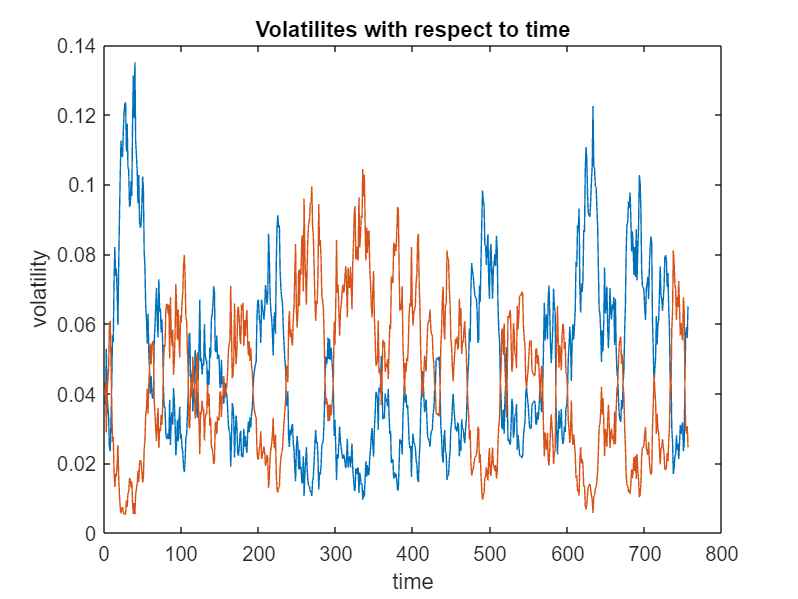


% Plots volatilities
plot(V(:,1))
hold on
plot(V_ant(:,1))
hold off
title('Volatilites with respect to time')
xlabel('time') 
ylabel('volatility') 

% Let's take maximum values of all simulations n
S_max = max(S);
S_ant_max = max(S_ant);

% Maturity prices
S_T = S(end, :);
S_ant_T = S_ant(end, :);

% Option prices for European up-and-in call option
Call_in = (S_max >= H).*max(S_T-K,0)*exp(-r*T);
Call_in_ant = (S_ant_max >= H).*max(S_ant_T-K,0)*exp(-r*T);
%Call_in = max(Call_in,0);

% Option prices to IV
IV =  blsimpv(S0, K, r, T, Call_in);
IV_ant = blsimpv(S0, K, r, T, Call_in_ant);

Standard_price = mean(Call_in)

Standard_price = 0.1679

Antithetic_price = mean(Call_in_ant)

Antithetic_price = 0.1747